# Create and Train a Deep Learning Model

Script for creating and training a deep learning network with the following properties:

Run this script to create the network layers, import training and validation data, and train the network. The network layers are stored in the workspace variable `layers`. The trained network is stored in the workspace variable `net`.

To learn more, see [Generate MATLAB Code From Deep Network Designer](matlab:helpview('deeplearning','generate_matlab_code')).

Auto-generated by MATLAB on 09-May-2024 23:13:24

## Load Initial Parameters

Load parameters for network initialization. For transfer learning, the network initialization parameters are the parameters of the initial pretrained network.

trainingSetup = load("C:\Users\user\Desktop\Github Projects\matlab-deep-learning-designer\params_2024_05_09__23_12_54.mat");

## Import Data

Import training and validation data.

imdsTrain = imageDatastore("C:\Users\user\Desktop\Github Projects\matlab-deep-learning-designer\data","IncludeSubfolders",true,"LabelSource","foldernames");
[imdsTrain, imdsValidation] = splitEachLabel(imdsTrain,0.7,"randomized");

## Augmentation Settings

imageAugmenter = imageDataAugmenter(...
    "RandXReflection",true);

% Resize the images to match the network input layer.
augimdsTrain = augmentedImageDatastore([227 227 3],imdsTrain,"DataAugmentation",imageAugmenter);
augimdsValidation = augmentedImageDatastore([227 227 3],imdsValidation);

## Set Training Options

Specify options to use when training.

opts = trainingOptions("adam",...
    "ExecutionEnvironment","auto",...
    "InitialLearnRate",0.0001,...
    "MaxEpochs",10,...
    "Shuffle","every-epoch",...
    "ValidationFrequency",5,...
    "Plots","training-progress",...
    "ValidationData",augimdsValidation);

## Create Array of Layers

layers = [
    imageInputLayer([227 227 3],"Name","imageinput")
    convolution2dLayer([3 3],32,"Name","conv","Padding","same")
    reluLayer("Name","relu")
    maxPooling2dLayer([5 5],"Name","maxpool","Padding","same")
    convolution2dLayer([3 3],32,"Name","conv_1","Padding","same")
    reluLayer("Name","relu_1")
    fullyConnectedLayer(3,"Name","fc")
    softmaxLayer("Name","softmax")
    classificationLayer("Name","classoutput")];

## Train Network

Train the network using the specified options and training data.

Training on single GPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:03 |       41.67% |       33.33% |      13.4386 |     638.4087 |      1.0000e-04 |
|       5 |           5 |       00:00:04 |      100.00% |      100.00% |   0.0000e+00 |   0.0000e+00 |      1.0000e-04 |
|      10 |          10 |       00:00:05 |      100.00% |      100.00% |   0.0000e+00 |   0.0000e+00 |      1.0000e-04 |
|=========================================================================================

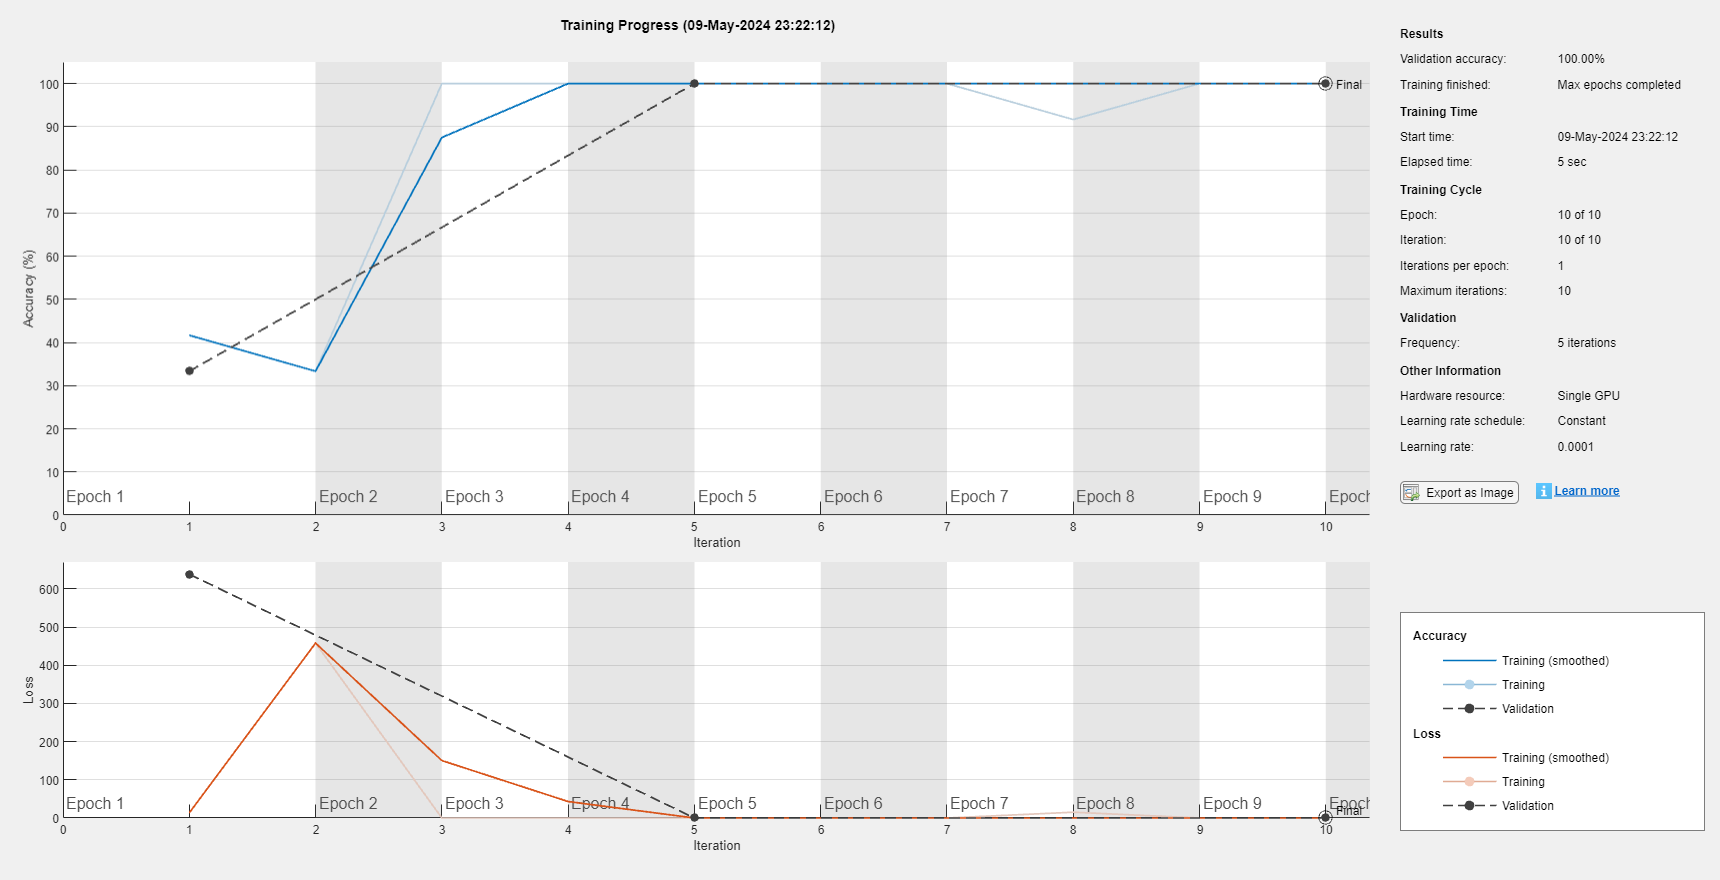

[net, traininfo] = trainNetwork(augimdsTrain,layers,opts);

## Test Result & Classification

inp = 'forest.jpg'

inp = 'forest.jpg'

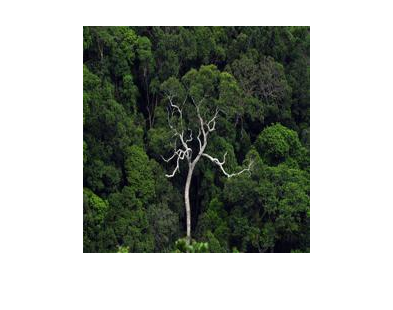

I = imread(inp);
figure, imshow(I)


class = classify(convnet, I)

class = categorical
     forest 


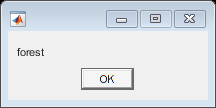

msgbox(char(class))